n = 0:15;
x = 0.84.^n;
y = circshift(x,5); %right circular shift 
[c,lags] = xcorr(x,y,10,'normalized'); %xcorr(s1,s2,maxlag_number,option)//normalize
[cx,lagsx]=xcorr(x,x)

cx =     0.0731    0.1485    0.2284    0.3153    0.4118    0.5208    0.6457    0.7902    0.9589    1.1568    1.3899    1.6654    1.9916    2.3786    2.8380    3.3839    2.8380    2.3786    1.9916    1.6654    1.3899    1.1568    0.9589    0.7902    0.6457    0.5208    0.4118    0.3153    0.2284    0.1485    0.0731


lagsx =    -15   -14   -13   -12   -11   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15


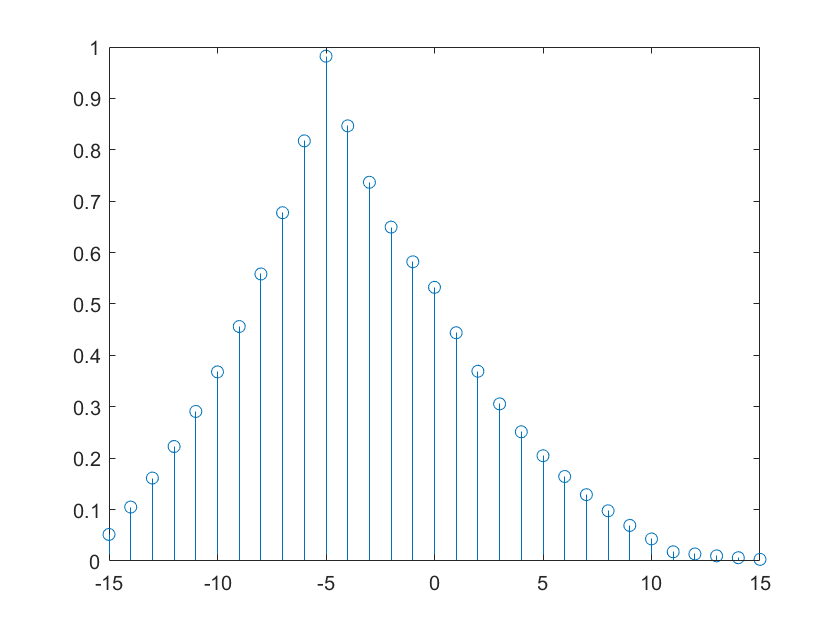

stem(lags,c)

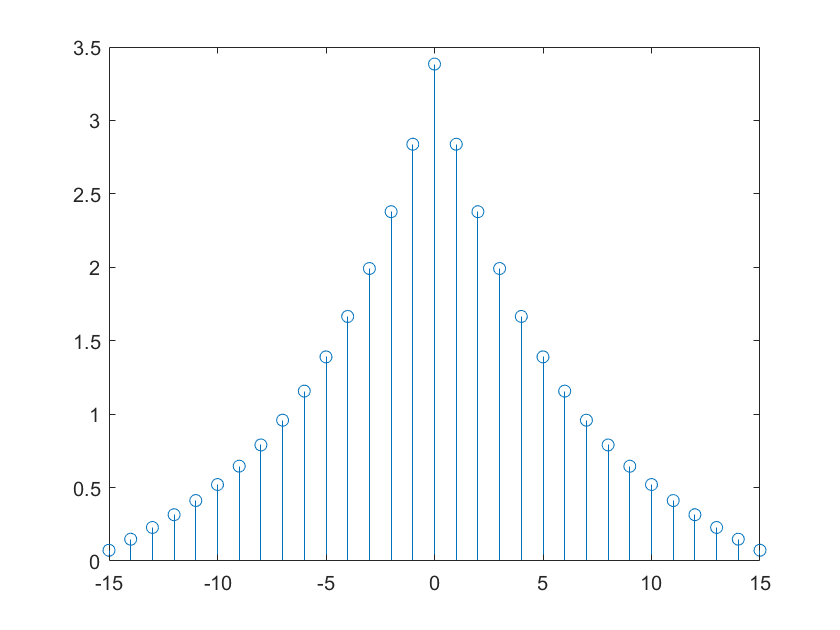

stem(lagsx,cx)